Strang 1.2 - Problem 18: Use *Livescript *in Matlab for this problem. Write a fininte difference approximation with $n=4$ unknowns to


$$\frac{d^2u}{dx^2} = x, \text{with boundary conditions }\  u(0)=0 \ \text{and }\ u(1) = 0$$


Solve for $u_1 ,u_{2\;} ,u_3 ,\mathrm{and}\;u_4$. Compare them to the true solution (use Calculus). Decrease your stepsize $h=\Delta x$ to now have $n=8$unkowns. How does your solution change? How small need $\Delta x$ be?

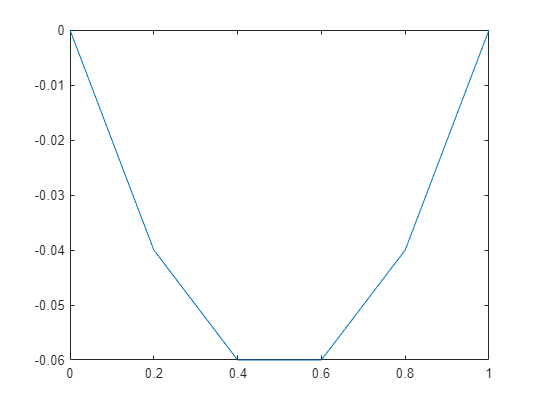

n = 4;
e = ones(n,1);
A = spdiags([e -2*e e],-1:1,n,n);
b = 1;
a = 0;
h = (b-a)/(n+1);

u0 = 0; uf = 0;
b_vec = 1/2*h.^2*ones(n,1);
b_vec(1) = b_vec(1)+u0;
b_vec(end) = b_vec(end)+uf;

u = A\b_vec;
u = [u0 u' uf];
x = 0:h:1;
plot(x,u)

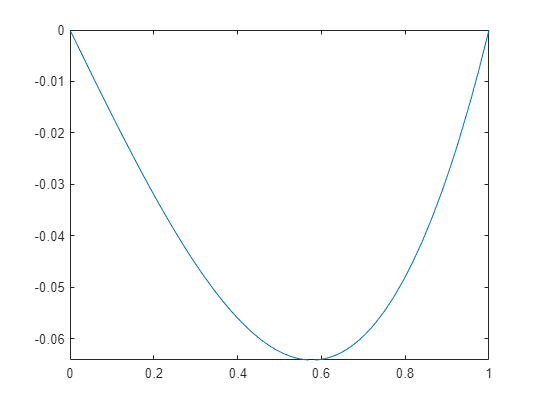

f = @(x) 1/6*(x.^3-x);
fplot(f,[0 1])

Besides comparing the graphs, we can look at the errors:

err = abs(f(u) - u)

err =          0    0.0467    0.0700    0.0700    0.0467         0


Then running everything again with $n=8$ gives:

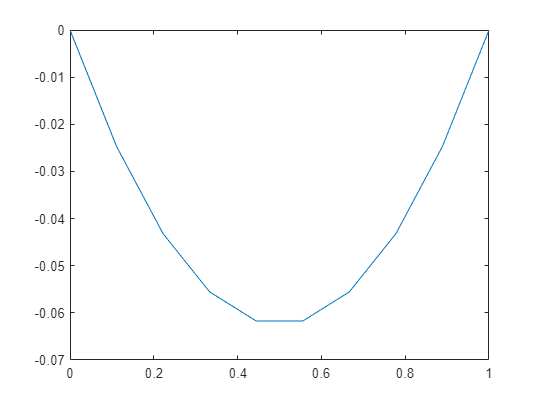

n = 8;
e = ones(n,1);
A = spdiags([e -2*e e],-1:1,n,n);
b = 1;
a = 0;
h = (b-a)/(n+1);

u0 = 0; uf = 0;
b_vec = 1/2*h.^2*ones(n,1); % not so sure why its 1/2h^2
b_vec(1) = b_vec(1)+u0;
b_vec(end) = b_vec(end)+uf;

u = A\b_vec;
u = [u0 u' uf];
x = 0:h:1;
plot(x,u)

f = @(x) 1/6*(x.^3-x);
fplot(f,[0 1])

Besides comparing the graphs, we can look at the errors:

err = abs(f(u) - u);

err(1:5)

ans =          0    0.0288    0.0504    0.0648    0.0720


err(6:end)

ans =     0.0720    0.0648    0.0504    0.0288         0
